filename = "AQUA_MODIS.20221005T044000.L2.SST.NRT.nc";

sst = ncread(filename, 'geophysical_data/sst');
longitude = ncread(filename, 'navigation_data/longitude');
latitude = ncread(filename, 'navigation_data/latitude');


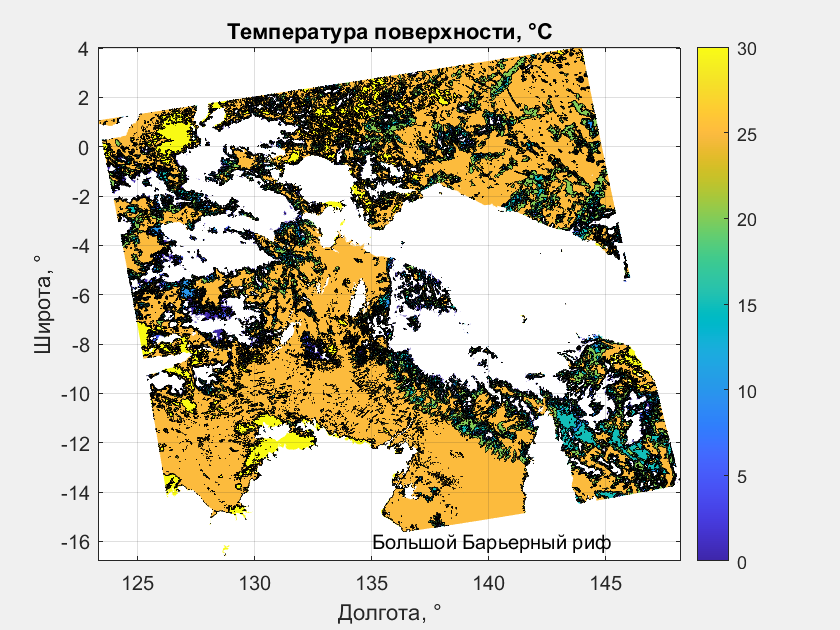

sst(sst<0) = NaN;
sst(sst>35) = NaN;

set(figure, 'Visible', 'on')
contourf(longitude, latitude, sst)
colorbar
grid on
title('Температура поверхности, °С')
xlabel('Долгота, °')
ylabel('Широта, °')
text(135, -16, "Большой Барьерный риф")